# 2024-2025-1 数学软件期中考试题(B)

班级：                       姓名：                     学号：                     

**考试时间：110+5分钟    考试形式：闭卷      总分：100**

- 请**先填写上面的班级姓名学号**。

- **闭卷**，只可查看MATLAB的help。在结束前5分钟完成答题，将你的答卷**导出为pdf 文件并提交**。

- 你提交的**文件名应改名为卷号班级姓名.pdf**，如“**B卷信计1231张三.pdf**”。

**一. 填空题：(4分 **$\times$ **10=40分)**

(1) 以下代码运行时将出错，其错误原因是：（   将函数名log当作自定义的变量名     ）  

log=log(3)

x =          0    0.7854    1.5708    2.3562    3.1416    3.9270    4.7124    5.4978    6.2832


log=log(4)

x =          0    0.7854    1.5708    2.3562    3.1416    3.9270    4.7124    5.4978    6.2832


(2) 下列的字符串，**哪些**可以作为MATLAB的变量名（     A, D      ）。

A. haida2024      B. 2024haida       C. haida.2024        D.  haida_2024

(3)  在MATLAB中，**分别**用冒号表达式和函数linspace()建立一个起点为 0，终点为 2$\pi$，步长为 $\frac{\pi}4$ 的数组 x.

x=0:pi/4:2*pi

$$x = \left(\begin{array}{ccccccccc} 0 & \frac{\pi }{4} & \frac{\pi }{2} & \frac{3\,\pi }{4} & \pi & \frac{5\,\pi }{4} & \frac{3\,\pi }{2} & \frac{7\,\pi }{4} & 2\,\pi \end{array}\right)$$

x=linspace(0,2*pi,9)

$$x = \left(\begin{array}{ccccccccc} 0 & \frac{\pi }{4} & \frac{\pi }{2} & \frac{3\,\pi }{4} & \pi & \frac{5\,\pi }{4} & \frac{3\,\pi }{2} & \frac{7\,\pi }{4} & 2\,\pi \end{array}\right)$$

也可以建立符号数组

x=0:sym(pi)/4:2*pi

A =      1     2     3
     4     5     6
     7     8     9


x=linspace(0,2*sym(pi),9)

A =      0     1     3
     2     3     6
     4     5     9


(4)  在MATLAB中，**不直接输入**，用命令生成矩阵 $A=\left(\begin{array}{ccc}1&2&3\\4&5&6\\7&8&9\end{array}\right)$，再用一条命令将第 1, 2 列减去第3列的 $\frac13$.

A=reshape(1:9,3,3)'

M =      3     1     1
     1     3     1
     1     1     3


A(:,1:2)=A(:,1:2)-A(:,3)/3

ans =      5
     5
     5


(5) 已知矩阵 $M=\left(\begin{array}{ccc} 3&1&1\\1&3&1\\1&1&3\end{array}\right)$，求它的各行元素之和、行列式、特征值. 

M=ones(3)+2*eye(3)

ans = 20

sum(M,2)

ans =     2.0000
    2.0000
    5.0000


det(M)
eig(M)

(6) 用MATLAB命令判断下列线性方程组 $\left(\begin{array}{ccc} 3&1&1\\1&3&1\\1&1&3\end{array}\right)\left(\begin{array}{c}x_1\\x_2\\x_3\end{array}\right)=\left(\begin{array}{c}8\\4\\-2\end{array}\right)$是否有解，若有解则求出其解。

M=ones(3)+2*eye(3);
b=[8,4,-2]';
rank(M)==rank([M,b])

ans = logical
   1


x=M\b

x =     3.0000
    1.0000
   -2.0000


(7) 对函数 $y={\rm e}^{2x}$ 作Taylor展开至 7 次多项式.

syms x
y=exp(2*x);
taylor(y,x,'Order',8)

$$ans = \frac{8\,x^{7}}{315}+\frac{4\,x^{6}}{45}+\frac{4\,x^{5}}{15}+\frac{2\,x^{4}}{3}+\frac{4\,x^{3}}{3}+2\,x^{2}+2\,x+1$$

(8) 建立符号函数 $f(x) = {\rm e}^{2x}\sin x$，并做下列操作：

      (a) 求二阶导； (b) 求 $\displaystyle\int_0^{\pi} f(x) dx.$

syms x
f=exp(2*x)*sin(x);
df2=diff(f,2)

$$df2 = 4\,{\mathrm{e}}^{2\,x}\,\cos\left(x\right)+3\,{\mathrm{e}}^{2\,x}\,\sin\left(x\right)$$

intf=int(f,x,0,pi)

$$intf = \frac{{\mathrm{e}}^{2\,\pi }}{5}+\frac{1}{5}$$

(9) 求函数 $f(x)={\rm e}^{-x^2}\sin 5x$ 在(2, 3)上的极小值点及极小值。

[x,fval]=fminbnd(@(x)exp(-x.^2)*sin(5*x),2,3)

x = 2.0612

fval = -0.0110

(10) 求方程 ${\rm e}^{-x^2}\sin 5x=0$ 在 x0= 1 附近的根。

x=fzero(@(x)exp(-x^2)*sin(5*x),1)

x = 1.2566

**二. 程序设计题，以下8个题任选5个完成（5、6题至少选1个），每题12分。**

1. 已知一个函数 $y=f(x)$上的若干个采样点的取值如下表所示：

  
$$\begin{array}{c|c|c|c|c|c|c|c|c}x&-1.3&-1.0&-0.7&-0.4&-0.1&0.2&0.5&0.8\\\hline y&0.039&-1.952&-0.565&1.397&2.528&-1.049&-5.749&-4.747\end{array}$$


用4次多项式作拟合，求拟合函数的系数向量p。并在同一坐标系中用红色圆圈表现采样点，用蓝色实线表现拟合函数(取步长为0.02)，给出图例。

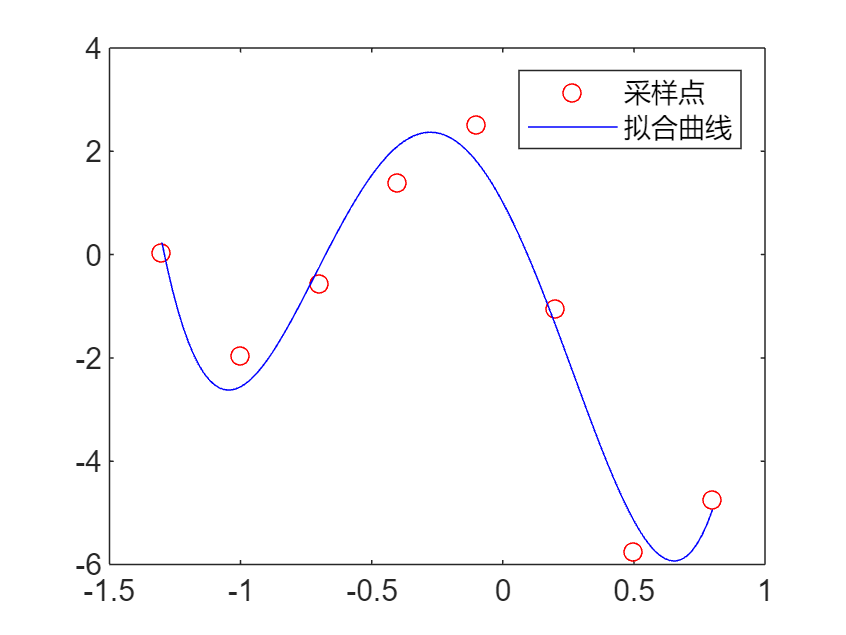

x=-1.3:0.3:0.8;
y=[0.039,-1.952,-0.565,1.397,2.528,-1.049,-5.749,-4.747];
p=polyfit(x,y,4);
xt=-1.3:0.02:0.8;
yt=polyval(p, xt);
figure,
plot(x,y,'ro',xt,yt,'b')
legend('采样点','拟合曲线')

2. 已知圆周率的一个近似计算公式为： 


$$\pi=3+\sum\limits_{n=1}^{\infty}\frac{(-1)^{n+1}}{n(n+1)(2n+1)},$$


分别用循环和数组运算求 $\pi$ 的近似值，计算 n 从1到100 的级数和，并用 fprintf 输出小数点后15位小数。

% 以下用循环求级数和
mypi=3;
up=1;
for n=1:100    
    down=n*(n+1)*(2*n+1);
    mypi=mypi+up/down;
    up=-up;
end
fprintf('圆周率的近似值为：%.15f',mypi)

圆周率的近似值为：3.141592410971982

% 以下用数组运算求级数和
n=1:100;
up=(-1).^(n+1);
down=n.*(n+1).*(2*n+1);
mypi=3+sum(up./down);
fprintf('圆周率的近似值为：%.15f',mypi)

圆周率的近似值为：3.141592410971981

3. 在同一图形窗口中，分左右子图，绘制函数 $z=10{\rm e}^{-x^2-y^2}\sin(x^2+y^2)$分别在方域 $x,y\in[-4, 4]$上的图形和在圆域 $x^2+y^2\leq16$上的图形。坐标轴上采用等长刻度。

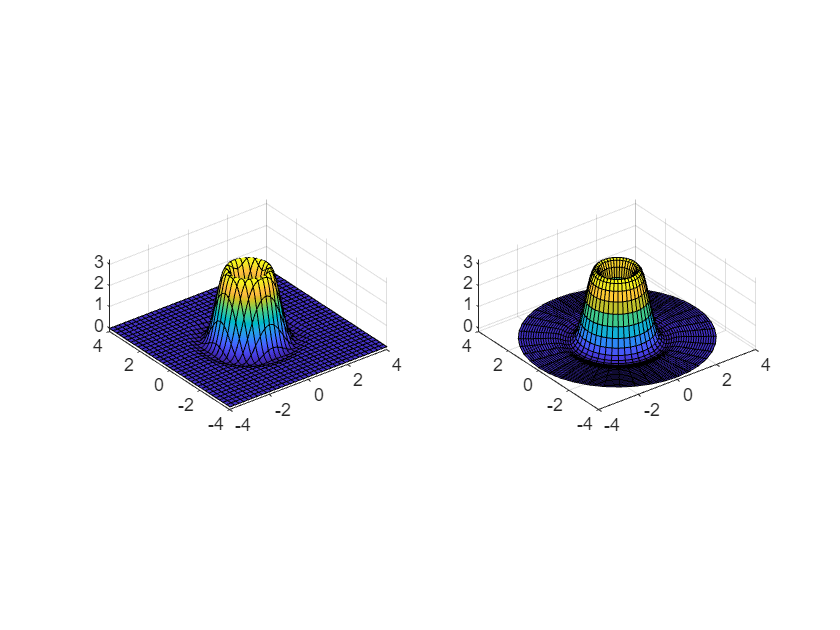

figure
subplot(121)
z=@(x,y)10*exp(-x.^2-y.^2).*sin(x.^2+y.^2);
fsurf(z,[-4,4,-4,4]), axis equal
subplot(122)
r=0:0.1:4;
t=0:pi/20:2*pi;
[r,t]=meshgrid(r,t);
x=r.*cos(t);
y=r.*sin(t);
surf(x,y,z(x,y)), axis equal

f=[3,1,2];
A=[1,1,1;-2,-3,1];
b=[7;1];
Aeq=[4,2,1];
beq=12;
[x,fval]=linprog(f,A,b,Aeq,beq)

问题无界。


x =

     []


fval =

     []



4.  据世界钢铁协会统计，2023年主要工业国的粗钢产量如下表所示（单位：百万吨）

 
$$\begin{array}{c|c|c|c|c|c|c}\text{国家}&\text{中国}&\text{印度}&\text{日本}&\text{美国}&\text{俄罗斯}&\text{其他}\\\hline \text{粗钢}&1019.1&140.2&87.0&80.7&75.8&485.4\end{array}$$


请在同一图形窗口中，分左右子图表现上述数据，左子图中用条形图表现各国粗钢产量，横坐标为为国家名，标题为“各国粗钢产量”；右子图中用饼图表现所占比例，标题为“比例”。

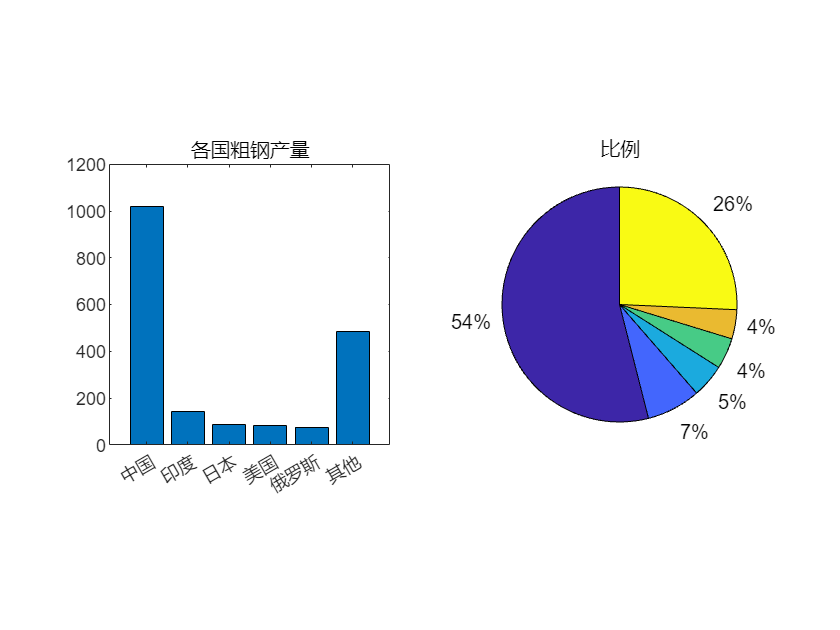

steel=[1019.1, 140.2, 87.0, 80.7, 75.8, 485.4];
country={'中国','印度','日本','美国','俄罗斯','其他'};
figure,
subplot(121),bar(country,steel),axis square
title('各国粗钢产量')
subplot(122), pie(steel)
title('比例')

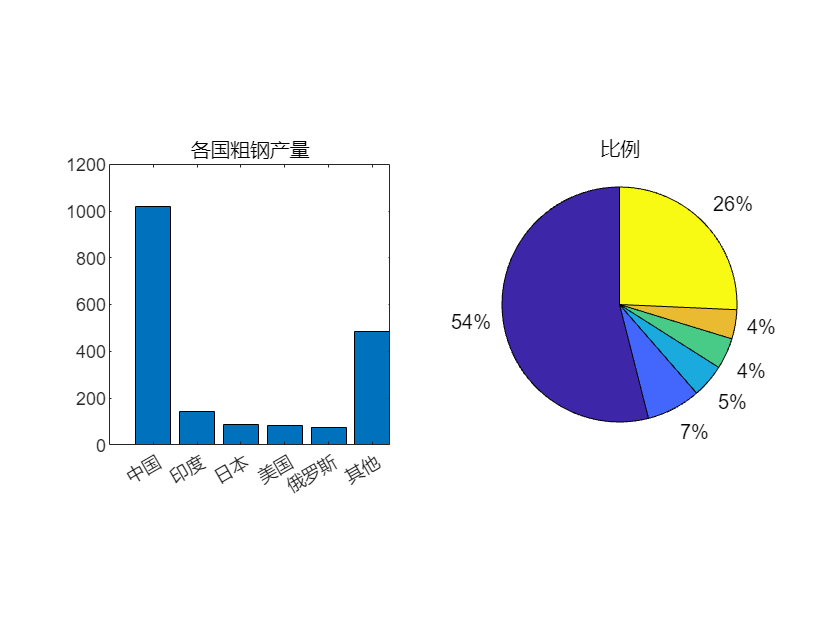

steel=[1019.1, 140.2, 87.0, 80.7, 75.8, 485.4];
country={'中国','印度','日本','美国','俄罗斯','其他'};
figure,
subplot(121),bar(steel),axis square
xticklabels(country)
title('各国粗钢产量')
subplot(122), pie(steel)
title('比例')

5. 如果一个数本身是素数，且它的各位数字之和也是一个素数，则称为完美的素数。如113是素数，而其各位数字之和5也是素数，故113是完美的素数。编写程序，求出[100,200]上所有完美的素数。注：判断素数可用MATLAB自有函数 isprime().

wms=[];
for k=100:200
    a=fix(k/100);  % 百位数
    c=mod(k,10); % 个位数
    b=mod((k-c)/10, 10);  % 十位数
    if isprime(k) && isprime(a+b+c)
        wms=[wms,k];
    end
end
disp(['[100,200]上所有完美的素数有：',num2str(wms)])

[100,200]上所有完美的素数有：101  113  131  137  139  151  157  173  179  191  193  197  199


6. 求立方根 $\sqrt[3]{C}$ 的一种迭代公式为 $x_{k+1}=\frac13(4x_k-\frac{x_k^4}C).$ 编写程序，利用该公式求 $\sqrt[3]{5}$。迭代初始值可以取$x_0=1$，当满足 $|x_{k+1}-x_k|<10^{-8}$ 时，停止迭代，并取 $x_{k+1}$为立方根的近似值。最后输出$\sqrt[3]{5}$的近似值，保留小数点后8位。

C=5;
x0=1;
x1=(4*x0-x0^4/C)/3;
while abs(x1-x0)>=1e-8
    x0=x1;
    x1=(4*x0-x0^4/C)/3;
end
fprintf('5的立方根的近似值为：%.8f', x1)

5的立方根的近似值为：1.70997595

x=mycuberoot(5, 1e-8);
fprintf('3的平方根的近似值为：%.8f', x)

3的平方根的近似值为：1.70997595

7.  求解优化问题： $\min\limits_x(3x_1+x_2+2x_3)\\ {\rm s.t.} \begin{cases}x_1+x_2+x_3\leq 7,\\-2x_1-3x_2+x_3\geq 1,\\4x_1+2x_2+x_3=12,\\x_1,x_2\geq 0.\end{cases}$

f=[3,1,2];
A=[1,1,1;2,3,-1];
b=[7,-1];
Aeq=[4,2,1];
beq=12;
lb=[0,0,-inf];
[x,fval]=linprog(f,A,b,Aeq,beq,lb)

找到最优解。



x =     1.8333
         0
    4.6667


fval = 14.8333

8.  求解优化问题： $\begin{array}{l}\max\limits_x f(x)=-x_1^2-0.3x_1x_2-2x_2^2+8x_1+27x_2,\\{\rm s. t.}\begin{cases}x_1+x_2\leq 100,\\x_1-2x_2\leq0,\\ 3x_1+2x_2=6.\\x_1,x_2\geq 0 \end{cases}\end{array}$

H=[2,0.3;0.3,4];  % 注：原问题为求max，H,f取负变成最小值问题
f=-[8,27];
A=[1,1;1,-2];
b=[100,0];
Aeq=[3,2];
beq=6;
lb=[0,0];
[x,fval]=quadprog(H,f,A,b,Aeq,beq,lb)


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


x =     0.0000
    3.0000


fval = -63.0000

fval=-fval

fval = 63.0000

% 以下当做约束非线性优化问题求解
fun=@(x)x(1)^2+0.3*x(1)*x(2)+2*x(2)^2-8*x(1)-27*x(2);
A=[1,1;1,-2];
b=[100,0];
Aeq=[3,2];
beq=6;
lb=[0,0];
x0=rand(2,1);
[x,fval]=fmincon(fun,x0,A,b,Aeq,beq,lb)


找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


x =     0.0000
    3.0000


fval = -63.0000

fval=-fval

fval = 63.0000

% 以上的各题如果需要定义函数的话，请写在以下的代码框中：

function x=mycuberoot(C,tol)
%MYCUBEROOT: 求立方根（第6题函数定义）
% mycuberoot(C, tol): 求数C的立方根，tol为收敛精度
x0=1;
x=(4*x0-x0^4/C)/3;
while abs(x-x0)>=tol
    x0=x;
    x=(4*x0-x0^4/C)/3;
end
end